## Dane wejściowe

clear all
load("data\mass_data.mat","Iyy","Mass")
load("data\enviroment_data.mat","dynamic_pressure","v_sound")
load("data\wing_geometry.mat","S","MAC")
load("data\flight_cases_data.mat", "mach")
load("data\longitudinal_data.mat")
load("data\longitudinal_dimnsional_derivatives.mat")

## Wyznaczanie macierzy:

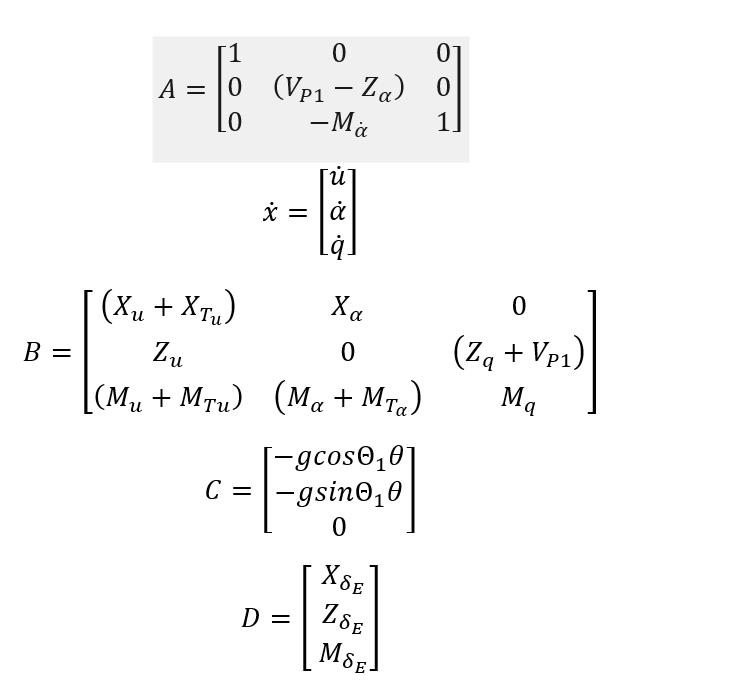

for i=1:1
    for o=2:2
        syms t u(t) alfa(t) q(t) delta(t)
        A= [1 0 0 ; 0 (Vp1(i,o)-Zalpha(i,o)) 0 ; 0 -Malphadot(i,o) 1];
        B= [(Xu(i,o)+Xtu(i,o)) Xalpha(i,o) 0 ; Zu(i,o) 0 (Zq(i,o)+Vp1(i,o)) ; (Mu(i,o)+Mtu(i,o)) (Mtalpha(i,o)+Mtalpha(i,o)) Mq(i,o)];
        C= [-gravity_acceleration(1)  0  0];
        D= [ XdeltaE(i,o)  ZdeltaE(i,o)  MdeltaE(i,o)];
        eqn1 = diff(u(t)) == (B(1,1)*u(t) + B(1,2)*alfa(t) + B(1,3)*q(t) + C(1) + D(1)*angleE(t)) / A(1,1);
        eqn2 = diff(alfa(t)) == (B(2,1)*u(t) + B(2,2)*alfa(t) + B(2,3)*q(t) + C(2) + D(2)*angleE(t)) / A(2,2);
        eqn3 = diff(q(t)) == (B(3,1)*u(t) + B(3,2)*alfa(t) + B(3,3)*q(t) + C(3) + D(3)*angleE(t)) / A(3,3);
        eqns = [eqn1, eqn2, eqn3];
        u0= 0;
        q0=0;
        alfa0=0;
        conds = [u(0)==u0, alfa(0)==alfa0, q(0)==q0]; 
        [x1Sol(t), x2Sol(t), x3Sol(t)] = dsolve(eqns, conds);
    end
    t=linspace(0,100,1000);
    u1=double(x1Sol(t))
    alfa1=double(x2Sol(t))
    theta1=double(x3Sol(t))
    deltaE1= angleE(t)
    save("data\values","u1","alfa1","theta1")
end

## Wykresownik

tiledlayout(2,2);
nexttile
plot(t,rad2deg(deltaE1))
xlabel('time[s]')
ylabel('\delta_E [\circ]')
grid minor
nexttile
plot(t,u1)
xlabel('time[s]')
ylabel('u [ft/s]')
grid minor
nexttile
plot(t,rad2deg(alfa1))
xlabel('time[s]')
ylabel('\alpha [\circ]')
grid minor
nexttile
plot(t,rad2deg(theta1))
xlabel('time[s]')
ylabel('\theta [\circ]')
grid minor


function deltaE= angleE(t)
    valuer=deg2rad(3);
    deltaE=valuer*(heaviside(t-3)-heaviside(t-6)-heaviside(t-23)+heaviside(t-26));
end